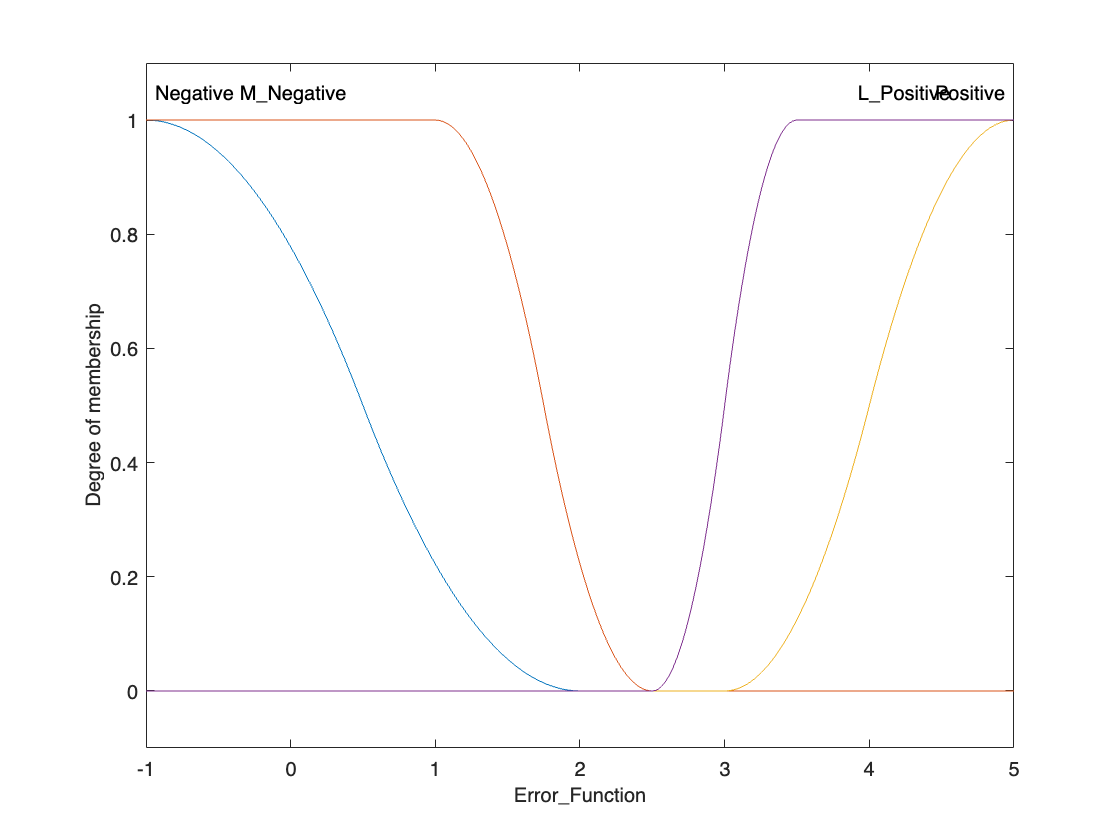

%Neurofeedback Fuzzy inference system
%% Version V1
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier
% Herrara-Vega, Gustavo Rodriguez 
% Date - March 29th, 2022
% Email - madlsh3517@gmail.com

cFNIRS = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 1, ...
    'NumOutputs', 1, 'NumOutputMFs', 2, ...
    'AddRule', 'none');

%Inputs

cFNIRS.Inputs(1).Name = 'Error_Function';
cFNIRS.Inputs(1).Range = [-1, 5]; 

cFNIRS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cFNIRS.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
cFNIRS.Inputs(1).MembershipFunctions(1).Parameters = [-1 2];

cFNIRS.Inputs(1).MembershipFunctions(2).Name = 'M_Negative';
cFNIRS.Inputs(1).MembershipFunctions(2).Type ='zmf'; %Z-shaped memebership function
cFNIRS.Inputs(1).MembershipFunctions(2).Parameters = [1 2.5];

cFNIRS.Inputs(1).MembershipFunctions(4).Name = 'L_Positive';
cFNIRS.Inputs(1).MembershipFunctions(4).Type ='smf'; %S-shaped memebersh
cFNIRS.Inputs(1).MembershipFunctions(4).Parameters = [2.5 3.5];

cFNIRS.Inputs(1).MembershipFunctions(3).Name = 'Positive';
cFNIRS.Inputs(1).MembershipFunctions(3).Type ='smf'; %S-shaped memebersh
cFNIRS.Inputs(1).MembershipFunctions(3).Parameters = [3 5];


plotmf(cFNIRS, 'input', 1, 1000);

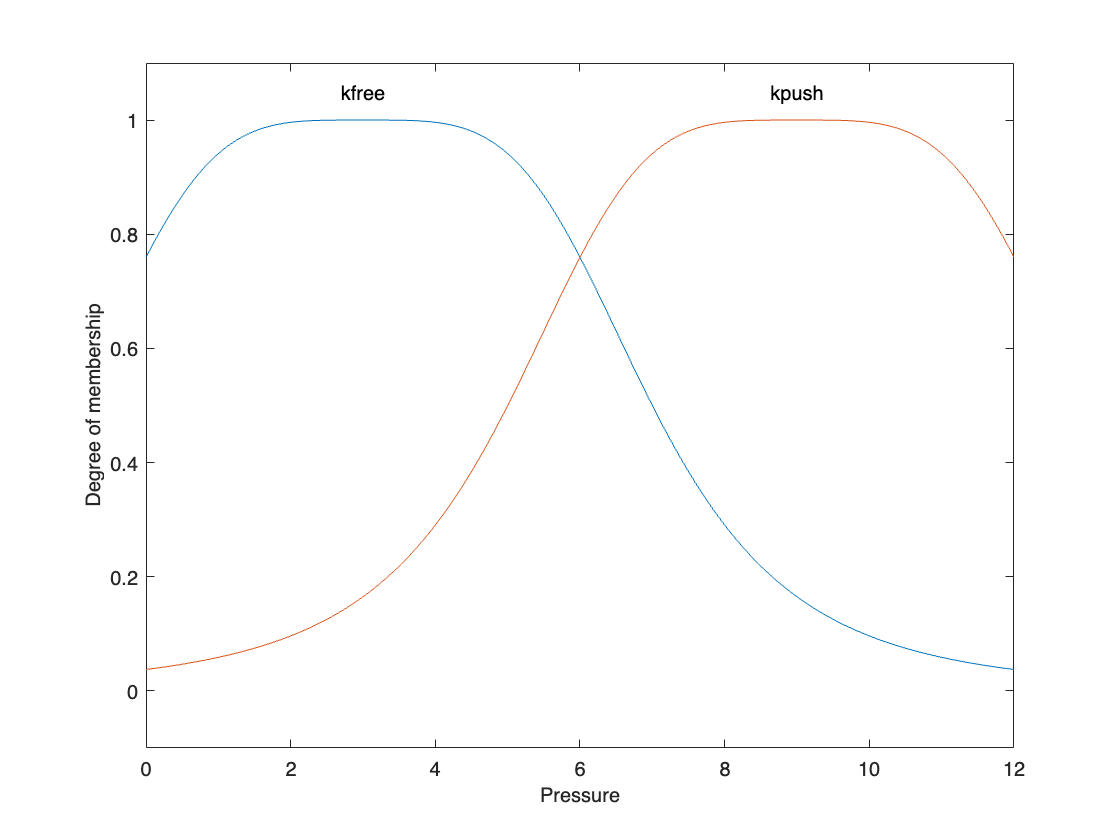

% Outputs
cFNIRS.Outputs(1).Name = 'Pressure';
cFNIRS.Outputs(1).Range = [0,12];

% cFNIRS.Outputs(1).MembershipFunctions(1).Name = 'free'; %Negative Low alternative
% cFNIRS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
% cFNIRS.Outputs(1).MembershipFunctions(1).Parameters = [0,2,0];

cFNIRS.Outputs(1).MembershipFunctions(1).Name = 'kfree'; %Negative Low alternative
cFNIRS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS.Outputs(1).MembershipFunctions(1).Parameters = [4,2,3];

cFNIRS.Outputs(1).MembershipFunctions(2).Name = 'kpush'; %Negative Low alternative
cFNIRS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS.Outputs(1).MembershipFunctions(2).Parameters = [4,2,9];

% cFNIRS.Outputs(1).MembershipFunctions(4).Name = 'push'; %Negative Low alternative
% cFNIRS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf'; %Generalized bell-shaped membership function
% cFNIRS.Outputs(1).MembershipFunctions(4).Parameters = [5,2,10];


plotmf(cFNIRS, 'output', 1, 1000);

%rules

rules = ["If Error_Function is Positive then Pressure is kfree";...
         "If Error_Function is Negative then Pressure is kpush";...
         "If Error_Function is M_Negative then Pressure is kfree";...
         "If Error_Function is L_Positive then Pressure is kpush"];

cFNIRS = addRule(cFNIRS,rules);